# Tema 2.2 - Derivación Numérica

## Ejemplo 1 

Calcular la derivada en todos los puntos por forward difference y por backward difference.

x=[0:0.2:0.4];y=[0 0.7414 1.3718];
disp([x',y'])

         0         0
    0.2000    0.7414
    0.4000    1.3718



# Forward

(0.074140)/0.2

ans = 0.3707

# Backward

## Ejemplo 2

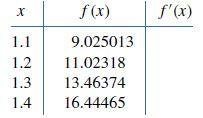

Calcular la derivada en todos los puntos con una fórmula de orden el más alto posible orden, O(h) i O(h^2)

x=linspace(1.1,1.4,4); y=[9.025013,11.02318,13.46374,16.44465];
disp([x',y'])

    1.1000    9.0250
    1.2000   11.0232
    1.3000   13.4637
    1.4000   16.4446



ERRORES. Los datos se corresponden a la función $y=e^{2x}$ la derivada es $y'=2e^{2x}$. Crear tabla para visualitzar error absoluto en las fórmulas usadas

## Ejemplo 3

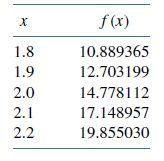

Calcular f'(2.0) con h=0.1 y h=02. Los datos son de f(x)=x*e^x, calcular los errores absolutos. Crear tabla para visualitzar error absoluto en las fórmulas usadas

x=linspace(1.8,2.2,5); y=x.*exp(x); disp([x',y'])

    1.8000   10.8894
    1.9000   12.7032
    2.0000   14.7781
    2.1000   17.1490
    2.2000   19.8550



#### Ejercicio 1 - CNGuia-Lab9

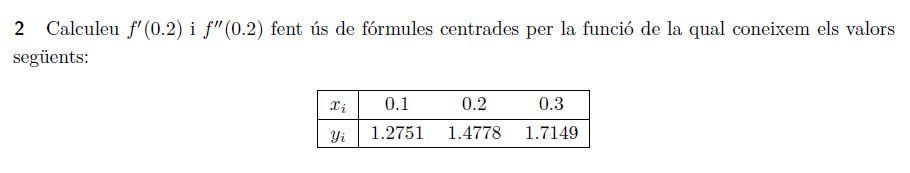

(1.7149-1.2741)/(2*0.1)

ans = 2.2040

(1.7149- 2*1.4778 +1.2741)/(0.1^2)

ans = 3.3400

#### Ejercicio 2 - CNGuia-Lab9

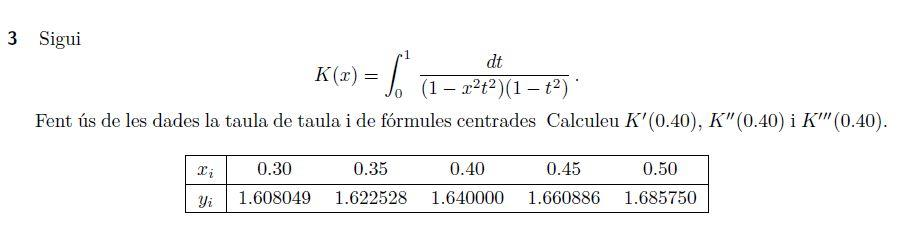

# Error en las fórmulas de diferenciación numérica 

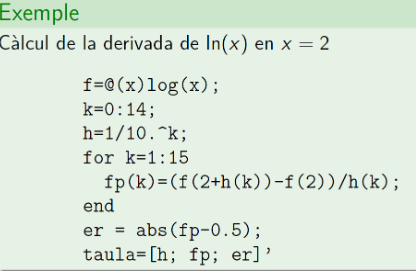

#### PRÀCTICA 22 - CNGuia-Lab9

format short g
f=@(x)log(x);
k = 0:14;
h = 1./10.^k;
fp = ones(length(h),1);
for n=1:length(k)
    fp(n) = (f(2+h(n))-f(2))/h(n);
end
er = abs(fp-0.5);
resultats = [k'  fp  er]

resultats =             0      0.40547     0.094535
            1       0.4879     0.012098
            2      0.49875    0.0012458
            3      0.49988   0.00012496
            4      0.49999     1.25e-05
            5          0.5     1.25e-06
            6          0.5   1.2494e-07
            7          0.5   1.3031e-08
            8          0.5   3.0387e-09
            9          0.5    4.137e-08


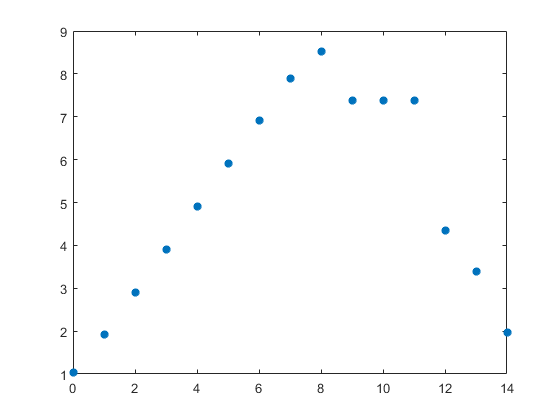

dc = -log10(er);
plot(k,dc,'*', 'LineWidth',2)

# Approximate Derivatives with diff

Use the `diff` function to approximate partial derivatives with the syntax `Y = diff(f)/h`, where `f` is a vector of function values evaluated over some domain, `X`, and `h` is an appropriate step size.

For example, the first derivative of `sin(x)` with respect to `x` is `cos(x)`, and the second derivative with respect to `x` is `-sin(x)`. You can use `diff` to approximate these derivatives.

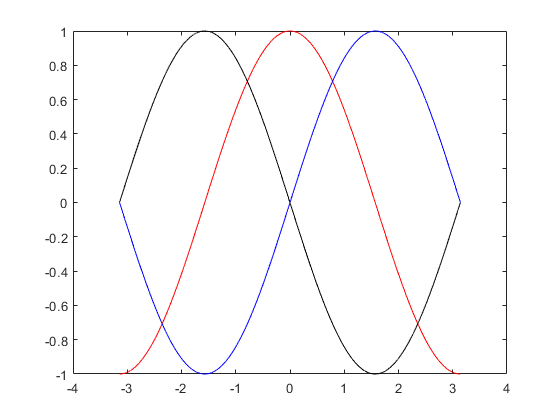

h = 0.001;       % step size
X = -pi:h:pi;    % domain
f = sin(X);      % range
Y = diff(f)/h;   % first derivative
Z = diff(Y)/h;   % second derivative
plot(X(:,1:length(Y)),Y,'r',X,f,'b', X(:,1:length(Z)),Z,'k')

In this plot the blue line corresponds to the original function, `sin`. The red line corresponds to the calculated first derivative, `cos`, and the black line corresponds to the calculated second derivative, `-sin`.

*Copyright 2015 The MathWorks, Inc.*

# Derivación simbólica con Matlab 

Ejemplos extraídos del help**Differentiate Function**

Find the derivative of the function `sin(x^2)`.

syms f(x)
f(x) = sin(x^2);
df = diff(f,x)

$$df(x) = 2\,x\,\cos\left(x^{2}\right)$$

Find the value of the derivative at `x = 2`. Convert the value to double.

df2 = df(2)

$$df2 = 4\,\cos\left(4\right)$$

double(df2)

ans = -2.6146

**Differentiation with Respect to Particular Variable**

Find the first derivative of this expression:

syms x t
diff(sin(x*t^2))

$$ans = t^{2}\,\cos\left(t^{2}\,x\right)$$

Because you did not specify the differentiation variable, `diff` uses the default variable defined by `symvar`. For this expression, the default variable is `x`:

symvar(sin(x*t^2),1)

$$ans = x$$

Now, find the derivative of this expression with respect to the variable `t`:

diff(sin(x*t^2),t)

$$ans = 2\,t\,x\,\cos\left(t^{2}\,x\right)$$

**Mixed Derivatives**

Differentiate this expression with respect to the variables `x` and `y`:

syms x y
diff(x*sin(x*y), x, y)

$$ans = 2\,x\,\cos\left(x\,y\right)-x^{2}\,y\,\sin\left(x\,y\right)$$

#### Document preparat per Mª Àngela Grau Gotés (prof. responsable MN)